# Second approach

Given the table with the patient in an arbitrary pose

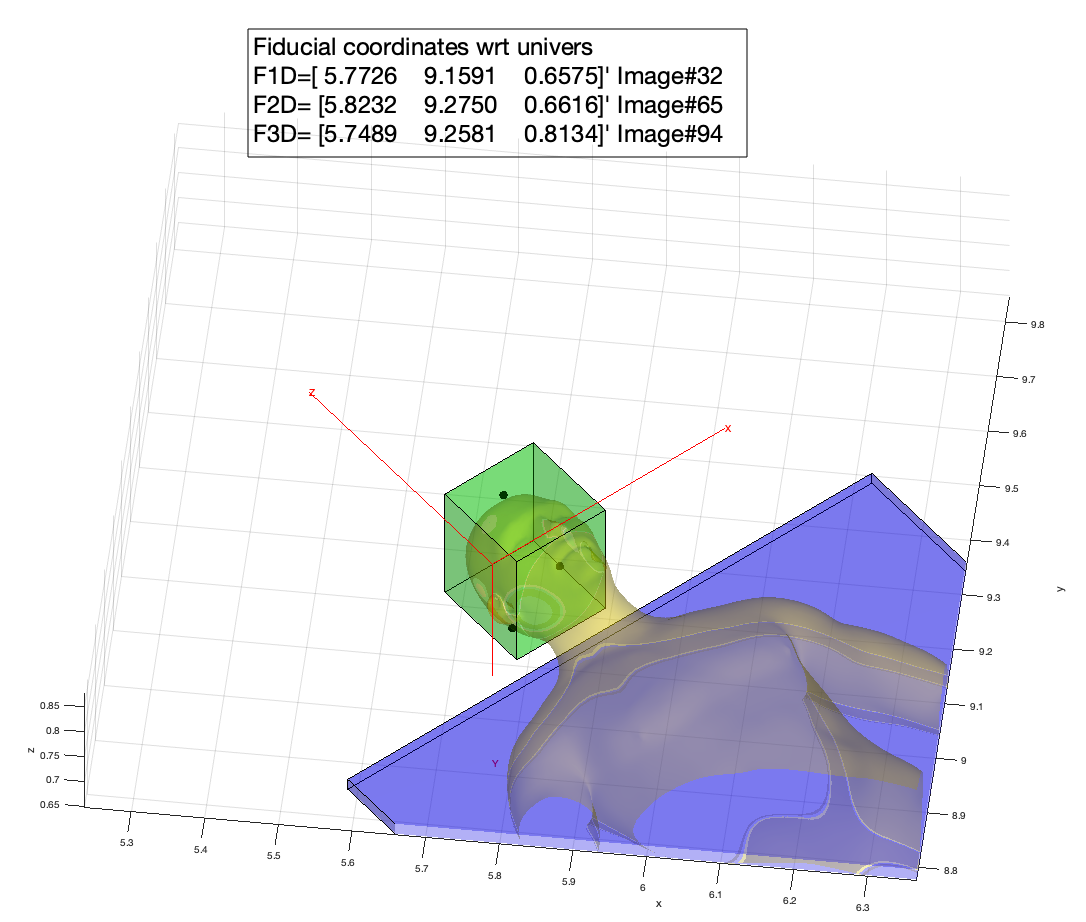

Open the new starting figure

open('3_Second_approach_Patient_pose.fig')
hold on

## Fiducial wrt {U}

Fiducials=open ('Fiducial_wrt_U.mat')

Error using open (line 87)
File 'Fiducial_wrt_U.mat' not found.

F1= Fiducials.FD2A_U(1:3,1)
F2= Fiducials.FD2A_U(1:3,2)
F3= Fiducials.FD2A_U(1:3,3)

## Fiducials wrt {I} 

From Dicom Images

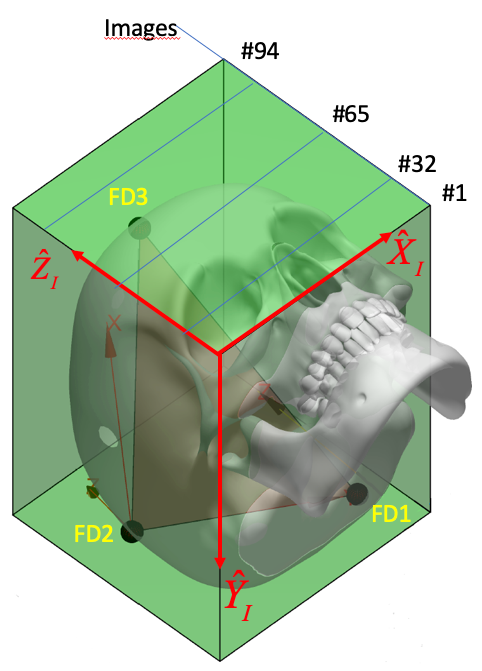

pitch =1.4
F1D = [0.06973 0.21496 0.032*pitch]'; %image #32
F2D = [0.18743 0.21088 0.065*pitch]'; %image #65
F3D = [0.12295 0.05915 0.094*pitch]'; %image #94


figure
trplot(eye(3),'Frame','I','color', 'r','length',0.4)
hold on
axis([-0.1 0.5 -0.1 0.5 -0.1 0.6])
view (-15,-65)

[X,Y,Z] = sphere;
r = 0.005;
X2 = X * r;
Y2 = Y * r;
Z2 = Z * r; 

surf(X2+F1D(1),Y2+F1D(2),Z2+F1D(3),'FaceColor',[0 1 0])
surf(X2+F2D(1),Y2+F2D(2),Z2+F2D(3),'FaceColor',[0 1 0])
surf(X2+F3D(1),Y2+F3D(2),Z2+F3D(3),'FaceColor',[0 1 0])

## Transform compound system equation

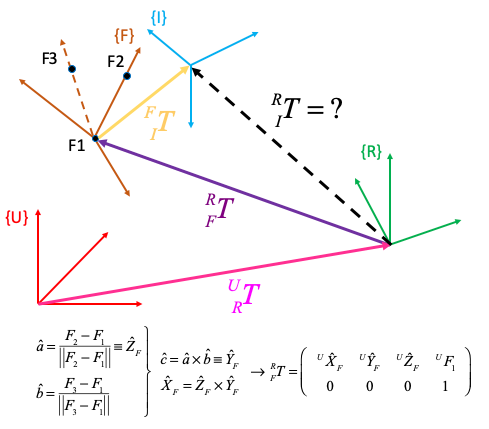

## T_F_R Frame Description

**Pay attention:** 

To emulate the action of measuring the fiducial wrt Robot Frame I gave you the fiducials coordinate wrt {U}. So, you need to place the robot Puma and infer the Fiducial wrt {R}

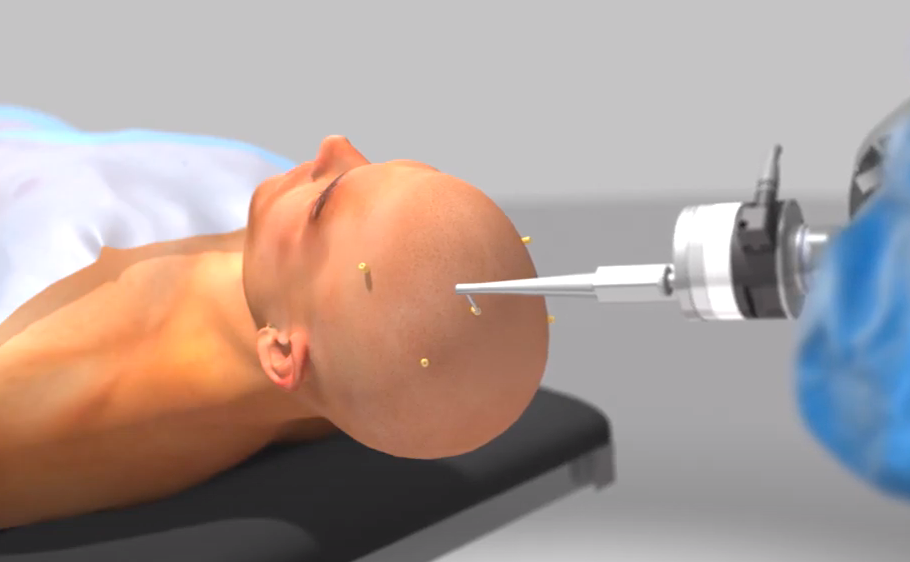

mdl_puma560
p560.base=transl(5.75,9.75,0)*trotz(-pi/4)
Robot_base=transl(p560.base)
%Fi_R=Fiducials.FD2A_U(1:3,:)- Robot_base'
Fi_R=inv(p560.base.T)*[Fiducials.FD2A_U(1:3,:);ones(1,3)]

Orientation

Zf = (Fi_R(1:3,2)-Fi_R(1:3,1))/norm(Fi_R(1:3,2)-Fi_R(1:3,1));
b=(Fi_R(1:3,3)-Fi_R(1:3,1))/norm(Fi_R(1:3,3)-Fi_R(1:3,1));
Yf = cross(Zf,b)/norm(cross(Zf,b));
Xf = cross(Zf,Yf)/norm(cross(Zf,Yf));
T_F_R = [[Xf;0] [Zf;0] [Yf;0] [Fi_R(:,1)]]
trplot(p560.base.T*T_F_R,'Frame','F','color', 'b','length',0.4)

det(T_F_R)

Check T_F_R as Going from {R} to {F}

RPY=tr2rpy(T_F_R,'zyx')
T_F1_U=p560.base.T*transl(Fi_R(1:3,1))*trotz(RPY(3))*troty(RPY(2))*trotx(RPY(1))

## T_I_F - Frame Description 

Extracted from the triangle F1D - F2D - F3D

Same procedure as before

ZfD = (F2D-F1D)/norm(F2D-F1D);
bD = (F3D-F1D)/norm(F3D-F1D);
YfD = cross(ZfD,bD)/norm(cross(ZfD,bD));
XfD = cross(ZfD,YfD)/norm(cross(ZfD,YfD));
T_I_F = [[XfD;0] [ZfD;0] [YfD;0] [F1D;1]]
det(T_I_F)

Check T_I_F as Going from {F to {I}

RPY=tr2rpy(T_I_F,'zyx')
T_I_F2=transl(F1D)*trotz(RPY(3))*troty(RPY(2))*trotx(RPY(1))

T_I_R=T_F_R*T_I_F
trplot(p560.base.T*T_F_R*trotz(RPY(3))*troty(RPY(2))*trotx(RPY(1)),'Frame','I','color', 'black','length',0.4)
F_R=T_I_R*[[F1D F2D F3D];ones(1,3)]
Fi_R